clear
close all
clf

load cuvicSVM.mat
modelo = cubicSVM;

% webcamlist;
% cam = webcam(1);
% imagen = snapshot(cam);

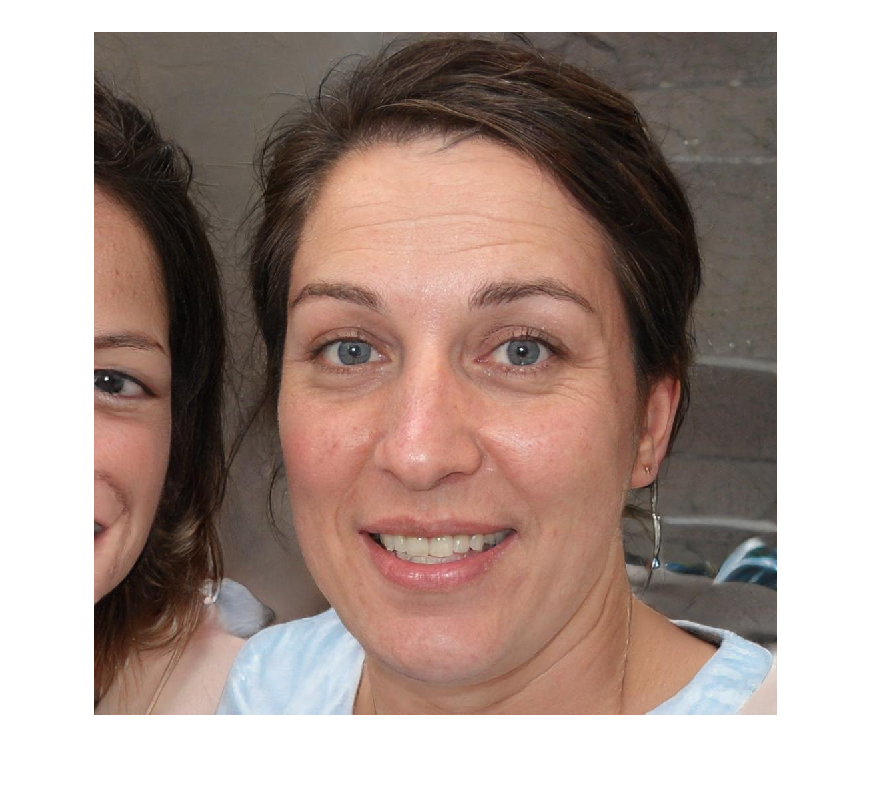

imagen = imread('DataFaces\images\00183c1c3c3c3c7f.jpg');
imshow(imagen)

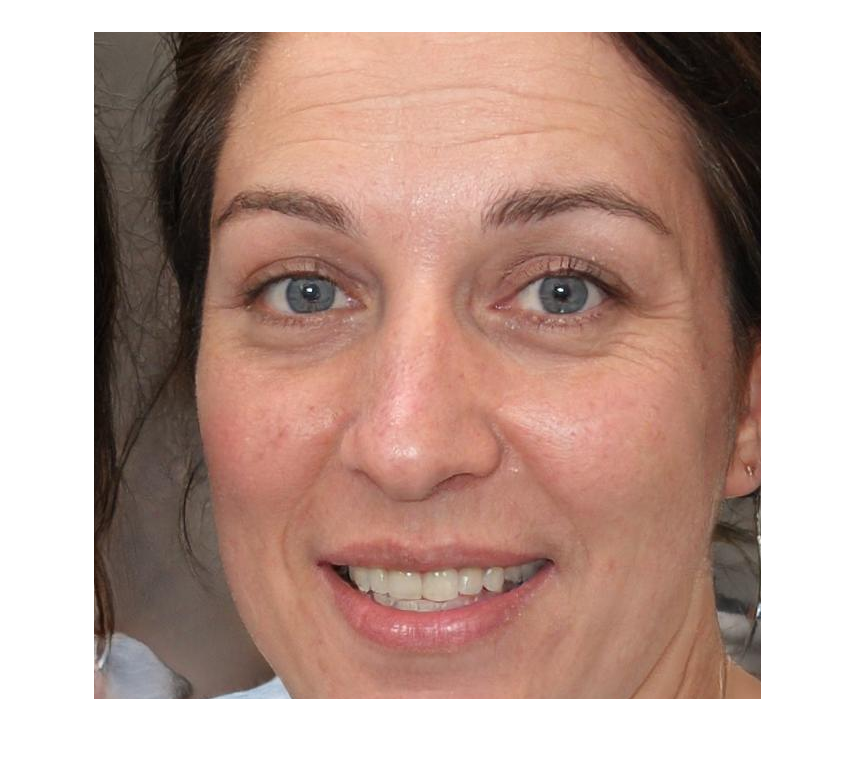

[cara, bbox] = searchFace(imagen);
imshow(cara)

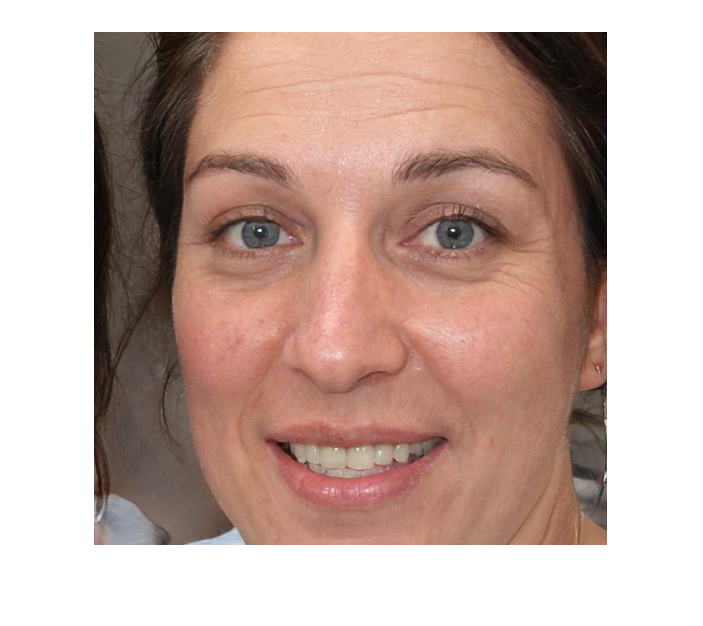

resizear = imresize(cara, 513/width(cara));
imshow(resizear)

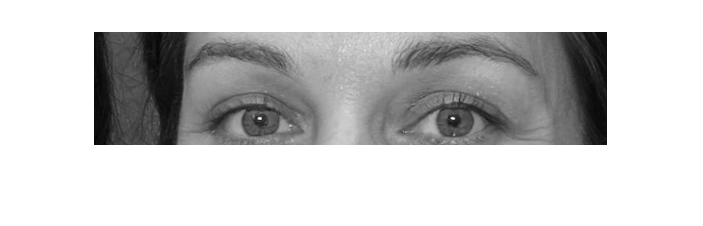

hayOjos = false;
inicio = 0;
soloOjos = [];
masOjos = [];

for i = 1:(round(113/2) - 1):(height(resizear)-113)
    trozo = resizear(i:(i+112), :, :);
    imshow(trozo)

    [score, label] = ejecutarPredictor(trozo, modelo);
    if (score == 1)
        masOjos = resizear((i - 60):(i+112), :, :);
        hayOjos = true;
        inicio = i;
        soloOjos = trozo;
        break;
    end
end

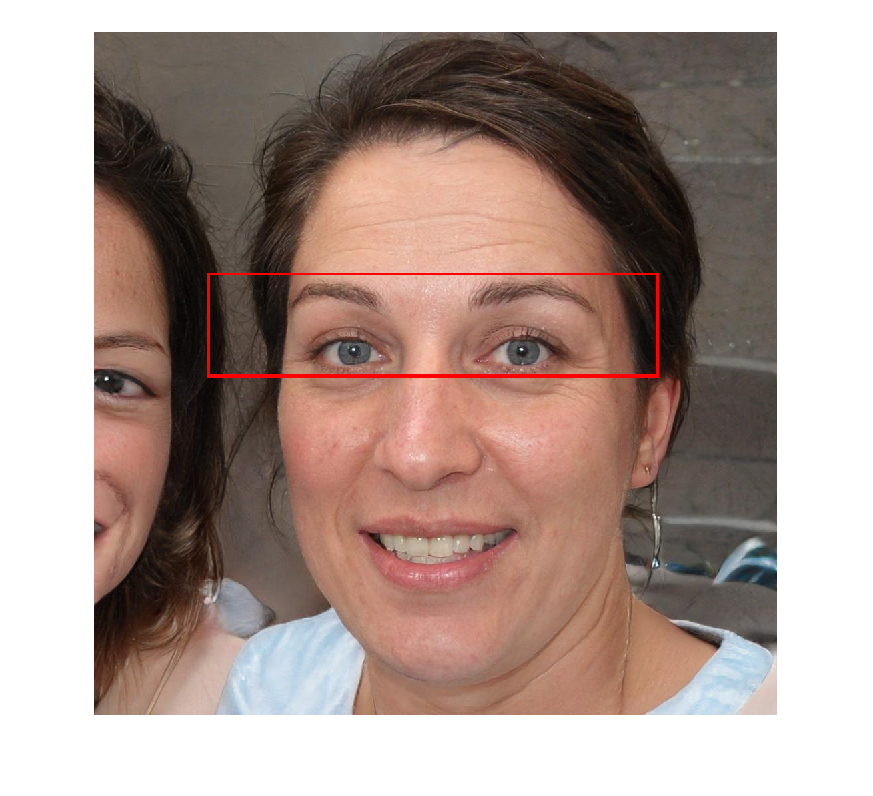

if hayOjos == true
    factorInverso = width(cara)/513;
    rectangulo =[bbox(1), bbox(2) + round(i*factorInverso), round(513 * factorInverso), round(113 * factorInverso)];
    
    outImg = imcrop(imagen, rectangulo);
    imshow(outImg)
    
    marca = false([height(imagen), width(imagen)]);
    marca(rectangulo(2):(rectangulo(2) + rectangulo(4)), rectangulo(1):(rectangulo(1) + rectangulo(3)) , :) = true;
    marcaGrande = imdilate(marca, strel('square', 10));
    marcaFinal = marcaGrande - marca;
    
    imagenMarcada = imoverlay(imagen, marcaFinal, 'red');
    
    imshow(imagenMarcada)
end